# Lights spiral

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

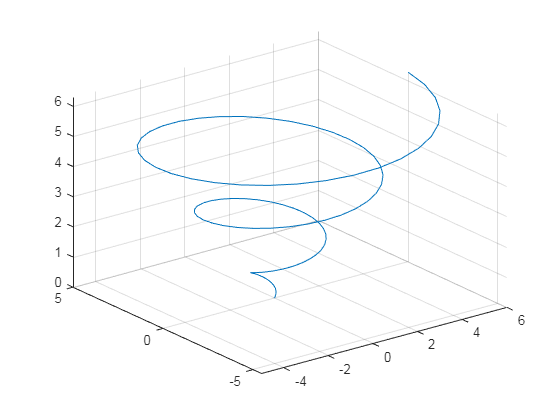

pl.scene_begin('scene_file', 'lights_spiral.pov', 'image_file', 'lights_spiral.png');
    pl.include("shapes");
    pl.global_settings("assumed_gamma 1");
    
    pl.camera('angle', 25, 'location', [22 18 13], 'look_at', [0 -0.8 4], 'type', 'perspective');
    pl.light('location',  [10 -10 10], 'color', [1 1 1]);
    pl.axis('length', [7 7 7]);
    
    % Marks amount
    nmarks = 100;
    
    % Create
    r = linspace(0,1,nmarks);
    theta = linspace (0, 6*pi, nmarks);
    x = r.*cos(theta) * 6;
    y = r.*sin(theta) * 6;
    z = theta / 3;
    
    % Display preview
    figure(1)
    plot3(x, y, z)
    grid on

    for n = 1:nmarks
        g =  (n / nmarks) / 1.5;
        pl.sphere('position', [x(n) y(n) z(n)], 'radius', 0.2, 'texture', 'Dark_Green_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        pl.light('location',  [x(n) y(n) z(n)], 'color', [g 1-g g]);
    end
    
pl.scene_end();

#### Render and display

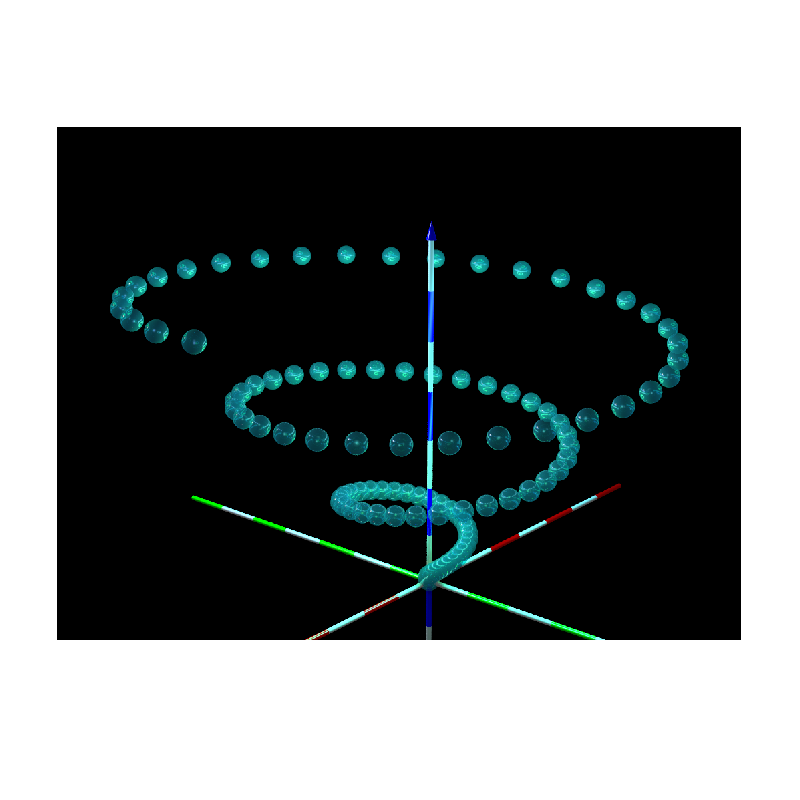

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 388.189143 seconds.
